显式欧拉法稳定性分析

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 10];
n=100;
h = 9/n

h = 0.0900

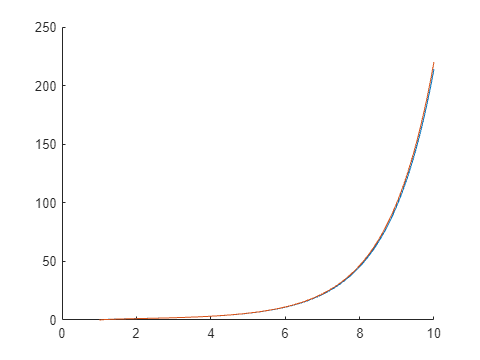

y0 = 0;
[X1,Y1] = ODE_ExplicitEuler( Hfun,t,h,y0 );
Y2=zeros(1,n+1);
Y3=zeros(1,n+1);
for i=1:n+1
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off

TAB=table(X1,Y1,Y3,Y2)

TAB = 101×4 table
     X1       Y1         Y3          Y2   
    ____    _______    _______    ________

       1          0          0           0
    1.09    0.24465    0.21546    0.029182
    1.18    0.42955    0.38501    0.044537
    1.27    0.57438    0.52239    0.051982
    1.36    0.69167    0.63685    0.054819
    1.45    0.78971    0.73476    0.054947
    1.54    0.87416    0.82067    0.053489
    1.63      0.949    0.89789    0.051118
    1.72     1.0171    0.96885    0.048245
    1.81     1.0805     1.0354    0.045119
     1.9      1.141     1.0991    0.041892
    1.99     1.1995     1.1609    0.038654
    2.08     1.2573     1.2218    0.035459
    2.17      1.315     1.2827    0.032333
    2.26     1.3733      1.344    0.029289
    2.35     1.4328     1.4065    0.026328


隐式欧拉法稳定性分析

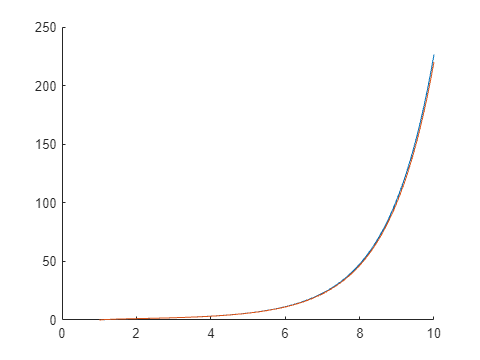

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 10];
n=100;
h = 9/n;
y0 = 0;
[X1,Y1] = ODE_ImplicitEuler( Hfun,t,h,y0 );
Y2=zeros(1,n+1);
Y3=zeros(1,n+1);
for i=1:n+1
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off

TAB=table(X1,Y1,Y3,Y2)

TAB = 101×4 table
     X1       Y1         Y3          Y2   
    ____    _______    _______    ________

       1          0          0           0
    1.09    0.19337    0.21546    0.022092
    1.18    0.35029    0.38501    0.034724
    1.27    0.48084    0.52239    0.041559
    1.36    0.59206    0.63685    0.044786
    1.45    0.68901    0.73476    0.045745
    1.54     0.7754    0.82067    0.045273
    1.63    0.85398    0.89789    0.043901
    1.72    0.92688    0.96885    0.041973
    1.81    0.99572     1.0354    0.039708
     1.9     1.0618     1.0991     0.03725
    1.99     1.1262     1.1609    0.034691
    2.08     1.1898     1.2218    0.032089
    2.17     1.2532     1.2827     0.02948
    2.26     1.3172      1.344    0.026884
    2.35     1.3822     1.4065    0.024312


改进型欧拉方法稳定性分析

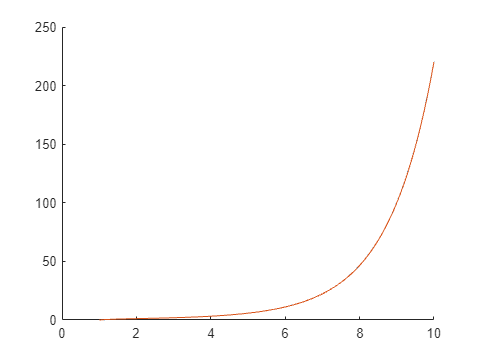

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 10];
n=100;
h = 9/n;
y0 = 0;
[X1,Y1] = ODE_ImprovedEuler( Hfun,t,h,y0 );
Y2=zeros(1,n+1);
Y3=zeros(1,n+1);
for i=1:n+1
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off

TAB=table(X1,Y1,Y3,Y2)

TAB = 101×4 table
     X1       Y1         Y3           Y2    
    ____    _______    _______    __________

       1          0          0             0
    1.09    0.21478    0.21546    0.00068853
    1.18    0.38401    0.38501     0.0010039
    1.27    0.52128    0.52239     0.0011195
    1.36    0.63572    0.63685     0.0011272
    1.45    0.73368    0.73476     0.0010769
    1.54    0.81968    0.82067    0.00099659
    1.63    0.89698    0.89789    0.00090178
    1.72    0.96805    0.96885    0.00080131
    1.81     1.0347     1.0354    0.00070004
     1.9     1.0985     1.0991    0.00060059
    1.99     1.1604     1.1609    0.00050423
    2.08     1.2214     1.2218    0.00041145
    2.17     1.2824     1.2827    0.00032229
    2.26     1.3438      1.344    0.00023653
    2.35     1.4063     1.4065    0.00015381


4阶Runge-Kutta方法稳定性分析

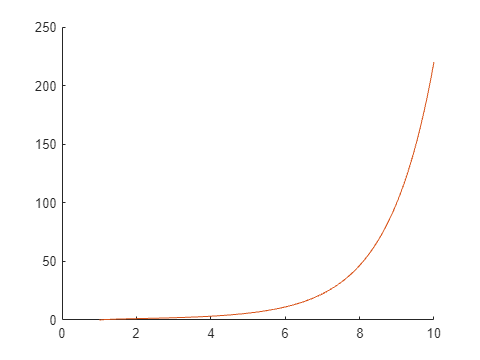

clc
clear
clf ('reset')
x0 = 1;
xn = 10;
y0 = 0;
n=100;
h = 9/n;
[X1,Y1] = RungeKutta4(x0, xn, y0, h);
Y2=zeros(1,n+1);
Y3=zeros(1,n+1);
for i=1:n+1
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off

TAB=table(X1,Y1,Y3,Y2)

TAB = 101×4 table
     X1       Y1         Y3           Y2    
    ____    _______    _______    __________

       1          0          0             0
    1.09    0.21546    0.21546    1.5303e-06
    1.18    0.38501    0.38501    2.1307e-06
    1.27    0.52239    0.52239    2.3015e-06
    1.36    0.63684    0.63685    2.2734e-06
    1.45    0.73476    0.73476    2.1568e-06
    1.54    0.82067    0.82067    2.0053e-06
    1.63    0.89788    0.89789    1.8454e-06
    1.72    0.96885    0.96885    1.6895e-06
    1.81     1.0354     1.0354    1.5434e-06
     1.9     1.0991     1.0991    1.4091e-06
    1.99     1.1609     1.1609    1.2872e-06
    2.08     1.2218     1.2218    1.1769e-06
    2.17     1.2827     1.2827    1.0775e-06
    2.26      1.344      1.344    9.8783e-07
    2.35     1.4065     1.4065    9.0694e-07
